close all; clc

% find equilibrium points
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
f1 = x1 + x1*x2

$$f1 = x_{1}+x_{1}\,x_{2}$$

f2 = -x2 + x2^2 + x1*x2 - x1^3

$$f2 = -{x_{1}}^{3}+x_{1}\,x_{2}+{x_{2}}^{2}-x_{2}$$


sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ 0\\ 1\\ -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ 1\\ -1\\ -1\\ -1 \end{array}\right)$$

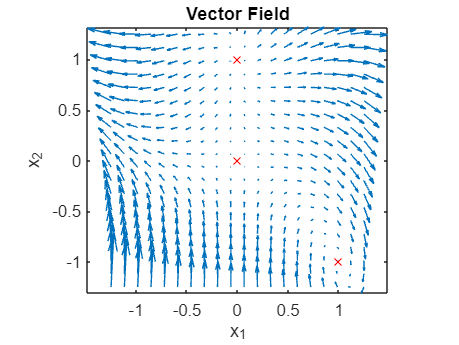


% Create vector field
x = linspace(-1.25,1.25,20);
y = linspace(-1.25,1.25,20);
[X,Y] = meshgrid(x,y);

DX = X + X.*Y;
DY = -Y + Y.^2 + X.*Y - X.^3;

quiver(X,Y,DX,DY,3); 
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

% draws x's on the equilibrium points
hold on;
for i=1:numel(sln.x1)
    if isreal(sln.x1(i)) && isreal(sln.x2(i))
        plot(sln.x1(i), sln.x2(i), 'rx')
    end
end
hold off